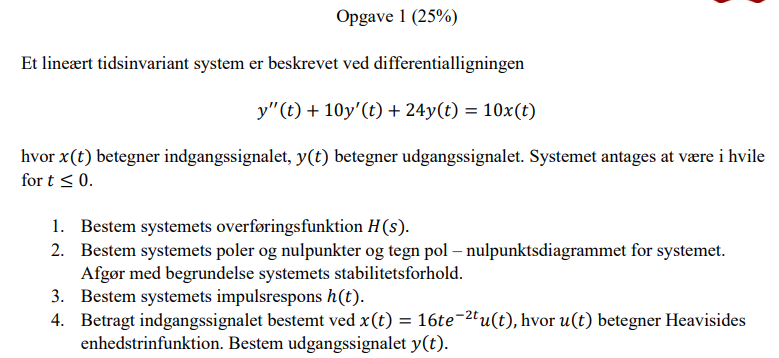

### **1. Bestem systemets overføringsfunktion H(s)**

% Definer nødvendige symbolske variable
syms s t;

% Opgave 1: Bestem systemets overføringsfunktion H(s)
% Koefficienterne for differentialligningen:
% y''(t) + 10y'(t) + 24y(t) = 10x(t)
a = [1, 10, 24];  % Koefficienter for y
b = [10];         % Koefficienter for x

disp('Opgave 1: Overføringsfunktion H(s)');

Opgave 1: Overføringsfunktion H(s)



[num, den, H_forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

===== KONVERTERING AF DIFFERENTIALLIGNING TIL OVERFØRINGSFUNKTION =====
 
TRIN 1: Identificer differentialligningen
Vi starter med koefficienterne for differentialligningen.
   a = [1, 10, 24] (output koefficienter)\nb = [10] (input koefficienter)
 
TRIN 2: Opskriv differentialligningen
Differentialligningen har følgende form:
   a_0 · y^(2) + a_1 · y^(1) + a_2 · y^(0) = b_0 · x^(0)
 
TRIN 3: Tag Laplacetransformationen af begge sider
Vi anvender Laplacetransformationen på hele ligningen under antagelse af nulbetingelser.
   L{y^(n)} = s^n·Y(s) - s^(n-1)·y(0) - ... - y^(n-1)(0)
 
TRIN 4: Antag nulbetingelser
Vi antager at alle startbetingelser er nul: y(0) = y'(0) = ... = y^(n-1)(0) = 0.
   Dette giver: L{y^(n)} = s^n·Y(s)
 
TRIN 5: Opskriv ligningen i Laplace-domæne
Efter Laplacetransformation får vi:
   a_0 · s^2 · Y(s) + a_1 · s^1 · Y(s) + a_2 · s^0 · Y(s) = b_0 · s^0 · X(s)
 
TRIN 6: Isolér overføringsfunktionen
Vi omskriver ligningen til at have Y(s) på venstre side og X(s) på høj


H_s = poly2sym(num, s) / poly2sym(den, s);
%H_s_str = H_forklaring.resultat;

disp(['H(s) = ', char(H_s)]);

H(s) = 10/(10*s + s^2 + 24)


### **2. Bestem poler, nulpunkter og stabilitetsforhold**

disp('Opgave 2: Poler og nulpunkter');

Opgave 2: Poler og nulpunkter


forklaringsOutput = ElektroMatBibTrinvis.analyserDifferentialligningMedForklaring(a);

===== ANALYSE AF DIFFERENTIALLIGNING =====
 
TRIN 1: Identificer differentialligningen
Vi starter med koefficienterne for differentialligningen.
   a = [1, 10, 24]
 
TRIN 2: Opskriv den homogene differentialligning
Den homogene differentialligning har følgende form:
   1 · y^(2) + 10 · y^(1) + 24 · y^(0) = 0
 
TRIN 3: Opskriv det karakteristiske polynomium
Det karakteristiske polynomium fås ved at erstatte y^(n) med λ^n.
   P(λ) = a_n·λ^n + a_(n-1)·λ^(n-1) + ... + a_1·λ + a_0
 
TRIN 4: Opskriv det karakteristiske polynomium
Det karakteristiske polynomium for denne differentialligning er:
   1 · λ^2 + 10 · λ^1 + 24 · λ^0 = 0
 
TRIN 5: Find rødderne i det karakteristiske polynomium
Rødderne bestemmer systemets opførsel.
   Rødderne i det karakteristiske polynomium er:\nλ_1 = -6.0000 (reel)\nλ_2 = -4.0000 (reel)
 
TRIN 6: Klassificér løsningstypen
For en andenordens ligning kan vi klassificere løsningstypen baseret på diskriminanten.
   Dette er en overdæmpet løsning (reelle forskellige r


% Poler:
poler = roots(a);
disp('Poler:');

Poler:


disp(poler);

   -6.0000
   -4.0000




% Nulpunkter:
nulpunkter = roots(num);
disp('Nulpunkter:');

Nulpunkter:


disp(nulpunkter);

### **3. Bestem systemets impulsrespons h(t)**

disp('Opgave 3: Impulsrespons h(t)');

Opgave 3: Impulsrespons h(t)



[h_t, h_forklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

===== INVERS LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere Laplace-transformationen, som skal konverteres tilbage til tidsdomænet.
   F(s) = 10/(10*s + s^2 + 24)
 
TRIN 2: Identificer funktionstypen som en brøk med kvadratisk nævner
Funktionen har en nævner på formen (s+a)²+b² med komplekse rødder.
   F(s) har nævneren (s+5)^2+1i^2
 
TRIN 3: Undersøg tællerens form
Afhængigt af tællerens form får vi forskellige typer af inverse transformationer.
   For kvadratiske nævnere kan vi typisk få sinus- eller cosinusfunktioner.
 
TRIN 4: Genkend mønstret for dæmpet sinus
Hvis F(s) = b/((s+a)²+b²), så er den inverse transformation en dæmpet sinus.
   L^(-1){b/((s+a)^2+b^2)} = e^(-at)sin(bt)
 
TRIN 5: Formuler det endelige resultat
Den inverse Laplacetransformation er en dæmpet sinusfunktion.
   f(t) = e^(-5t)sin(1it) for t ≥ 0
 
TRIN 6: Tilføj kausalitetsbetingelse
For LTI-systemer skal vi sikre at responset er 0 for t < 0, så vi tilfø


disp(['h(t) = ', char(h_t)]);

h(t) = sin(t*1i)*exp(-5*t)*heaviside(t)


### **4. Bestem udgangssignalet y(t)**

disp('Opgave 4: Udgangssignal y(t)');

Opgave 4: Udgangssignal y(t)



% Definer indgangssignalet x(t)
x_t = 16*t*exp(-2*t);

% Beregn Laplace-transformationen af x(t)
X_s = laplace(x_t, t, s);

% Beregn udgangssignalet y(t)
[y_t, y_forklaring] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(H_s, X_s, s, t);

===== BEREGNING AF UDGANGSSIGNAL =====
 
TRIN 1: Identificer systemet og indgangssignalet
Vi starter med at identificere systemets overføringsfunktion og indgangssignalets Laplacetransformation.
   H(s) = 10/(10*s + s^2 + 24)\nX(s) = 16/(s + 2)^2
 
TRIN 2: Beregn udgangssignalets Laplacetransformation
I frekvensdomænet er udgangssignalet produktet af overføringsfunktionen og indgangssignalet.
   Y(s) = H(s) · X(s) = 160/((s + 2)^2*(10*s + s^2 + 24))\nForenklet: Y(s) = 160/((s + 2)^2*(10*s + s^2 + 24))
 
TRIN 3: Forbered partialbrøkopløsning
For at finde den inverse Laplacetransformation, skal vi først udføre en partialbrøkopløsning.
   Y(s) = 160 / (s + 2)^2*(10*s + s^2 + 24)
 
TRIN 4: Udfør partialbrøkopløsning
Vi opløser den rationelle funktion i simple brøker.
   Y(s) =  /(s-( )) + □/(s-( )) +  /(s-( )) + □/(s-( ))
 
===== INVERS LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere Laplace-transformationen, som skal konverteres ti

disp(['y(t) = ', char(y_t)]);

y(t) = sum_of_terms*heaviside(t)


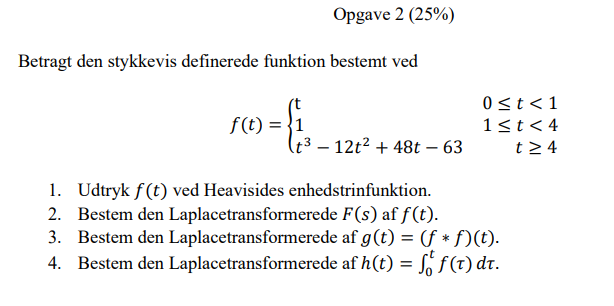

### 1. Udtryk f(t) ved Heavisides enhedstrinfunktion

% Definér symbolske variable
syms t

% Definér de tre stykker af funktionen
f1 = t;             % 0 ≤ t < 1
f2 = 1;             % 1 ≤ t < 4
f3 = t^3 - 12*t^2 + 48*t - 63;  % t ≥ 4

% Definér grænserne for intervallerne
graenser = [0, 1, 4, inf];

% Kald den nye funktion
[f_t, forklaring] = ElektroMatBibTrinvis.stykkevisFunktionMedForklaring({f1, f2, f3}, graenser, t);

% Vis resultatet
disp('f(t) udtrykt med Heavisides enhedstrinfunktion:');
disp(f_t);

### **2. Bestem den Laplacetransformerede F(s) af f(t)**

% Beregn Laplacetransformationen
syms s
[F_s, laplace_forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(f_t, t, s);
disp('Laplacetransformation F(s):');

F_s_simplify = simplify(F_s);
disp(F_s_simplify);

### **3. Bestem den Laplacetransformerede af g(t) = (f * f)(t)**

% Fra delopgave 2 har vi F(s)
% Brug foldningssætningen: L{f*f} = F(s)·F(s)
[G_s, forklaring3] = ElektroMatBibTrinvis.foldningssaetningMedForklaring(F_s, F_s, s, t);

G_s_simplify = simplify(G_s);
disp(G_s_simplify);

### 4. Bestem den Laplacetransformerede af h(t) = ∫₀ᵗ f(τ) dτ

% Antag at F_s er resultatet fra delopgave 2
syms s

% Anvend integralteoremet: L{∫₀ᵗ f(τ) dτ} = F(s)/s
H_s = F_s / s;

% Simplificér resultatet
H_s = simplify(H_s);

disp('Delopgave 4:');
disp('Laplacetransformationen af h(t) = ∫₀ᵗ f(τ) dτ:');
disp('H(s) = F(s)/s =');
disp(H_s);

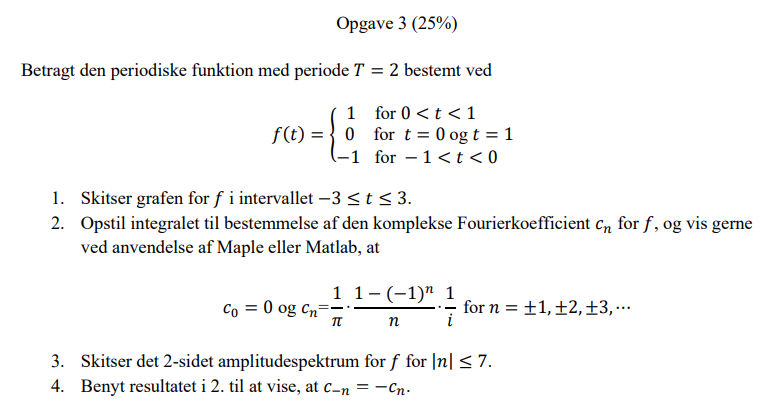

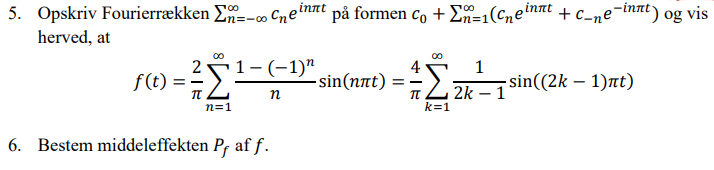

### 1.  Skitser grafen for 𝑓 i intervallet −3 ≤ 𝑡 ≤ 3.

% Evaluer funktionen over flere perioder
t_values = -3:0.01:3;
f_values = zeros(size(t_values));

for i = 1:length(t_values)
    t_mod = mod(t_values(i), 2);
    if t_mod == 0 || t_mod == 1
        f_values(i) = 0;
    elseif t_mod > 0 && t_mod < 1
        f_values(i) = 1;
    else % t_mod > 1 && t_mod < 2
        f_values(i) = -1;
    end
end

% Plot grafen
figure;
plot(t_values, f_values, 'LineWidth', 2);
grid on;
title('Graf for f(t) i intervallet [-3, 3]');
xlabel('t');
ylabel('f(t)');

### 2. Opstil integralet til bestemmelse af den komplekse Fourierkoefficient cn for f , og vis gerne ved anvendelse af Maple eller Matlab, 

% Definér den periodiske funktion
syms t
T = 2;
% Definer stykkevis funktion
f(t) = piecewise(0<t<1, 1, t==0 | t==1, 0, -1<t<0, -1);

% Beregn Fourier-koefficienter
[cn, forklaringsOutput] = ElektroMatBibTrinvis.fourierKoefficienterMedForklaring(f, t, T);

### 3. Skitser det 2-sidet amplitudespektrum for f for |n|≤ 7.

% Vis amplitudespektrum for |n| ≤ 7
n_values = -7:7;
amplitudes = zeros(size(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    if n == 0
        amplitudes(i) = abs(cn.c0);
    elseif n > 0
        amplitudes(i) = abs(cn.(['c' num2str(n)]));
    else
        amplitudes(i) = abs(cn.(['cm' num2str(abs(n))]));
    end
end

figure;
stem(n_values, amplitudes, 'filled');
grid on;
title('2-sidet amplitudespektrum for |n| ≤ 7');
xlabel('n');
ylabel('|c_n|');

### 4. Benyt resultatet i 2. til at vise, at c−n =−cn.

% Bedre verifikation af c_{-n} = -c_n relationen
disp('Verificering af c_{-n} = -c_n:');
for n = 1:7
    c_n = cn.(['c' num2str(n)]);
    c_neg_n = cn.(['cm' num2str(n)]);
    
    disp(['For n = ' num2str(n) ':']);
    disp(['c_' num2str(n) ' = ' num2str(c_n)]);
    disp(['c_-' num2str(n) ' = ' num2str(c_neg_n)]);
    
    % Håndter special-tilfældet hvor begge er (tæt på) nul
    eps = 1e-10;
    if abs(c_n) < eps && abs(c_neg_n) < eps
        disp(['Både c_' num2str(n) ' og c_-' num2str(n) ' er 0 - relationen c_{-n} = -c_n holder (0 = -0)']);
    else
        disp(['Forhold c_-' num2str(n) '/c_' num2str(n) ' = ' num2str(c_neg_n/c_n)]);
    end
    disp(' ');
end

### 5. 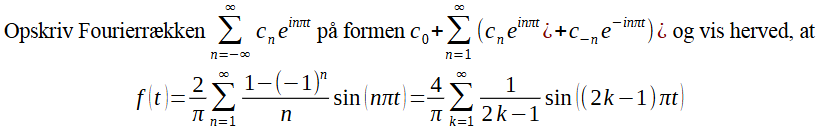

% Omskriv til sinus-række
%N = 20;  % Antal led
%[f_approx, fourierRaekkeOutput] = ElektroMatBibTrinvis.fourierRaekkeMedForklaring(cn, t, T, N);

% Definer funktionen og beregn koefficienter
% Omskriv til trigonometrisk form og identificer mønstre
[series_trig, omskrivningOutput] = ElektroMatBibTrinvis.fourierRaekkeOmskrivningMedForklaring(cn, t, T, 7);

### 6. Bestem middeleffekten P_f af f

% Beregn middeleffekten
[P, effektOutput] = ElektroMatBibTrinvis.parsevalTeoremMedForklaring(cn, 20);  % Bruger 20 led